%---To Do---
% 1) need to include validation data
% 2) need to create getPredictionData code
% 3) initial code testing

clear all
clc
k = 4;    % number of input bits
M = 2^k;  % modulation order
pow = 10; %see nb variable, length of train data
backOff = 1 %alternate between 1, 7, and 30. Units are in dB. 

backOff = 1


%dimensions
samples = 4; %window size
nb = 2^pow+1; %length of message to generate
chunks = 100; %for generating sets of data
val_size = floor(log2( (chunks * (2^pow)) /8 ));  %for validation data


%constellation diagram
constDiagram = comm.ConstellationDiagram('SamplesPerSymbol',1, ...
    'SymbolsToDisplaySource','Property','SymbolsToDisplay',100); 

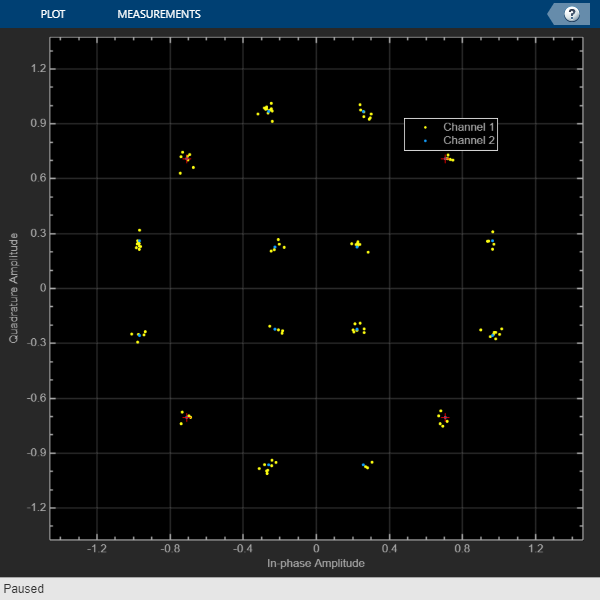

%generate training files 
for EbNo = [-2, 0, 3, 10, 15, 23, 50]; %SNR Value 

    [x_pred, y_pred, rx_pred, tx_pred] = getDVBSdata(M, samples, nb, EbNo, backOff);  %prediction data, only call once 
    [data, target, rx, tx ] = getDVBSdata(M, samples, nb, EbNo, backOff);  %first set of data
    [data_val, target_val, ~, ~] = getDVBSdata(M, samples, val_size, EbNo, backOff); 
    
    %visually check data
    constDiagram([rx, tx]); 

    
    %create large array
    x_train= zeros(size(data,1),size(data,2)*chunks);
    y_train = zeros(size(target,1),size(target,2)*chunks);
    
    tic 
    for iter = 1:chunks
        %saves
        x_train(:,((iter-1)*size(data,2)+1):(iter*size(data,2))) = data;
        y_train(:,((iter-1)*size(target,2)+1):(iter*size(target,2))) = target;
        if iter ~= chunks
            [data, target, ~, ~] = getDVBSdata(M, samples, nb, EbNo, backOff);
        end
    end
    toc

Elapsed time is 2.512141 seconds.


    
    %save to .mat file
    filename = sprintf('Data_SNR%02d', EbNo); %filename for saving data
    save(filename, 'x_train', 'y_train', 'x_pred', 'y_pred', 'rx_pred', 'tx_pred', 'data_val', 'target_val'); 
end 